# Diagram of signal processing  

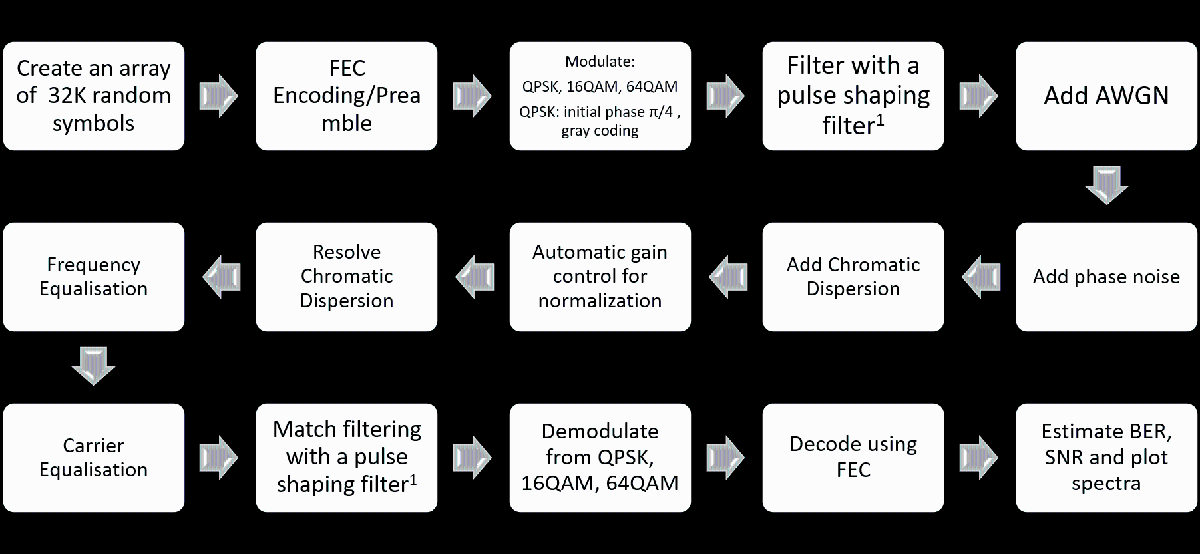

## Constants and Initial Conditions

%Resetting the rng seed
rng("default");
rng(1960);

enable_FEC = true;
enable_pulse_shaping = false;
enable_AWGN = false;
enable_phase_noise = false;
enable_chromatic_dispersion = false;
enable_frequency_equal = false;
enable_carrier_equal = false;
enable_plots = true;

num_symbols = 32*1024; 
symbol_rate = 10e9;
time_step = 1/symbol_rate;
linewidth = 100e3;
variance = 0.5*2*pi*linewidth*time_step;

## Forward Error Correction

if enable_FEC
    
    LDPC = dvbs2ldpc(3/4);
    encLDPC = comm.LDPCEncoder(dvbs2ldpc(3/4)); %#ok<*UNRCH> 

    % K: uncoded message length
    % N: coded message length
    LDPC_K = size(LDPC,2)-size(LDPC,1);
    LDPC_N = size(LDPC,2);
    
    M = 2; %BPSK
    symbols_bi = randi([0 M-1],num_symbols,1);
   
    %% nK-by-1 column vector of binary data where K = (3/4)*64800 = 48600n
    padding = (floor(length(symbols_bi)/LDPC_K)+1)*LDPC_K-length(symbols_bi); 
   
    padding = padding/2; %Halve for adding to both sides
        
    symbols_b = reshape(padarray(symbols_bi,padding,"both"),LDPC_K,[]);
    
    if(length(symbols_b)~=LDPC_K)
        error("Incorrect dimension for encoding");
    end
        
    %BPSK Encoding
    
    symbols_temp = nan(LDPC_N,size(symbols_b,2));
    
    for i=1:size(symbols_b,2)
        symbols_temp(:,i) = encLDPC(symbols_b(:,i));
    end
    symbols_b = reshape(symbols_temp,1,[]);
    
    %QPSK Encoding
    %LDPCs only take binary inputs, will have to convert symbols to bits, encode,
    %convert to symbols again,  and for decoding, symbols to bits, decode,
    %bits to symbols.
    
    M = 4; %QPSK
    symbols_qi = randi([0 M-1],num_symbols,1); 
    symbols_q = conversion(encLDPC,symbols_qi,M,LDPC_K,LDPC_N);
         
    %QAM16 Encoding
    %LDPCs only take binary inputs, will have to convert symbols to bits, encode,
    %convert to symbols again,  and for decoding, symbols to bits, decode,
    %bits to symbols. 
    
    M = 16; %16QAM
    symbols_16i = randi([0 M-1],num_symbols,1);
    symbols_16 = conversion(encLDPC,symbols_16i,M,LDPC_K,LDPC_N);
    
    
    M = 64; %64QAM
    symbols_64i = randi([0 M-1],num_symbols,1);
    symbols_64 = conversion(encLDPC,symbols_64i,M,LDPC_K,LDPC_N);
    
end

## Modulation

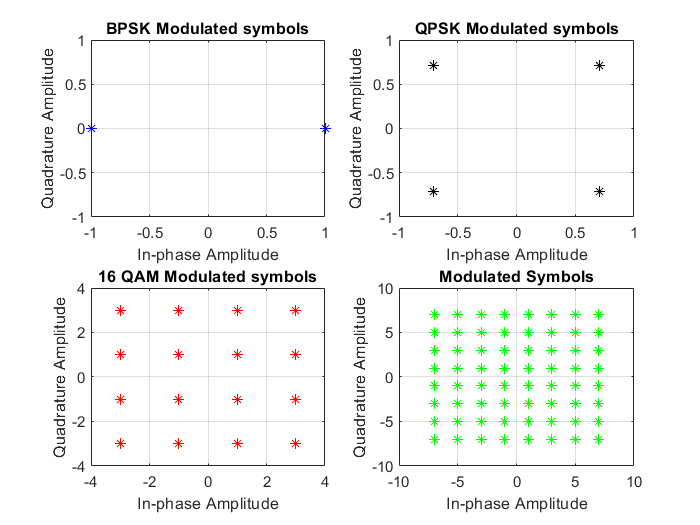

%BPSK
M = 2;
if (~enable_FEC)
symbols_b = randi([0 M-1],1,num_symbols);
end
bpsk_mod = pskmod(symbols_b,M,0,'gray');


%QPSK
M = 4;
if (~enable_FEC)
symbols_q = randi([0 M-1],1,num_symbols);
end
qpsk_mod = pskmod(symbols_q,M,pi/M,'gray');


%16QAM
M = 16;
if (~enable_FEC)
symbols_16 = randi([0 M-1],1,num_symbols);
end
qam16_mod = qammod(symbols_16,M,'gray');


%64QAM
M = 64;
if (~enable_FEC)
symbols_64 = randi([0 M-1],1,num_symbols);
end
qam64_mod = qammod(symbols_64,M,'gray');

if enable_plots
    figure
    subplot(2,2,1,gca);
    plot(bpsk_mod,'*','MarkerEdgeColor','blue','MarkerFaceColor',"blue");
    title("BPSK Modulated symbols");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    xlim([-1,1]);
    ylim([-1,1]);
    grid on;
    subplot(2,2,2);
    grid on;
    plot(qpsk_mod,'*','MarkerEdgeColor','black','MarkerFaceColor',"black");
    title("QPSK Modulated symbols");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    grid on;
    subplot(2,2,3);
    plot(qam16_mod,'*','MarkerEdgeColor','red','MarkerFaceColor',"red");
    title("16 QAM Modulated symbols");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    grid on;
    subplot(2,2,4);
    plot(qam64_mod,'*','MarkerEdgeColor','green','MarkerFaceColor',"green");
    title("64 QAM Modulated symbols");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    title("Modulated Symbols");
    grid on;
end

## Pulse Shaping and Upconverting

if enable_pulse_shaping
    
    corr = true;
    
    %Define Filter Constants
    
    tap_length = 32;
    upscaling = 8;
    Rolloff = 0.2;
    sample_rate = symbol_rate*upscaling;
    
    %Define Filter Objects
    
    tx_ps_filter = comm.RaisedCosineTransmitFilter("FilterSpanInSymbols",tap_length,"OutputSamplesPerSymbol",upscaling,"RolloffFactor",Rolloff,"Shape","Square root","Gain",1);
    rx_ps_filter = comm.RaisedCosineReceiveFilter("FilterSpanInSymbols",tap_length,"InputSamplesPerSymbol",upscaling,"RolloffFactor",Rolloff,"Shape","Square root","Gain",1);
    
    %Inspect Filters

    if enable_plots
    fvtool(tx_ps_filter);
    filter_taps = coeffs(tx_ps_filter);
    filter_taps = filter_taps.Numerator;

    raised_cosine_scope = dsp.SpectrumAnalyzer('SampleRate',sample_rate);
    matched_scope = dsp.SpectrumAnalyzer("SampleRate",symbol_rate);
    end
    
    %%% Note
    %If there is going to be a loss of information equal to the tap length
    %at the end of the symbols, consider using that range as padding?
    %%% End Note
    
    %Correleation signals for cross-corellation, can be replaced by
    %permanent preamble if deemed reasonable
    if corr
    corr_bpsk = bpsk_mod;
    corr_qpsk = qpsk_mod;
    corr_qam16 = qam16_mod;
    corr_qam64 = qam64_mod;
    end
    
    
    %Filter Transmitted Signals
    bpsk_mod = tx_ps_filter(bpsk_mod')';
    qpsk_mod = tx_ps_filter(qpsk_mod')';
    qam16_mod = tx_ps_filter(qam16_mod')';
    qam64_mod = tx_ps_filter(qam64_mod')';
    
    
    
end

## AWGN

if enable_AWGN
    
    %AWGN with an SNR of 20dB
    
    bpsk_mod = awgn(bpsk_mod,40,"measured");
    qpsk_mod = awgn(qpsk_mod,40,"measured");
    qam16_mod = awgn(qam16_mod,40,"measured");
    qam64_mod = awgn(qam64_mod,40,"measured");
    
    
    %Plots
    if enable_plots
    figure
    subplot(2,2,1,gca);
    scatter(real(bpsk_mod),imag(bpsk_mod));
    title("BPSK Symbols with AWGN");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    subplot(2,2,2);
    scatter(real(qpsk_mod),imag(qpsk_mod));
    title("QPSK Symbols with AWGN");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    subplot(2,2,3);
    scatter(real(qam16_mod),imag(qam16_mod));
    title("QAM16 Symbols with AWGN");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    subplot(2,2,4);
    scatter(real(qam64_mod),imag(qam64_mod));
    title("QAM64 Symbols with AWGN");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    end
    
end

## Phase Noise

if enable_phase_noise
    
    %Generate Phase Noise
    rng(1960);
    
    num_samples = length(bpsk_mod);
    
    phase_noise = randn(1,num_samples);

    random_walk_phase_noise = cumsum(sqrt(variance)*phase_noise);
    
    t = (1:num_samples)*time_step*1e9; %in nanoseconds
    
    %Can try mixing phase noise with awgn noise to set its SNR
    
    %Apply Phase Noise
    
    bpsk_mod = bpsk_mod.*exp(1j*random_walk_phase_noise);
    qpsk_mod = qpsk_mod.*exp(1j*random_walk_phase_noise);
    qam16_mod = qam16_mod.*exp(1j*random_walk_phase_noise);
    qam64_mod = qam64_mod.*exp(1j*random_walk_phase_noise);
    
    
    if enable_plots
    figure
    plot(t,random_walk_phase_noise,t,filtfilt(ones(100,1)/100,1,random_walk_phase_noise));
    title('Phase noise over time with \Delta\lambda= 100 kHz');
    xlabel("time (ns)");
    ylabel("Phase (rads)");
    legend("phase noise","smoothed phase noise");
    
    figure
    subplot(2,2,1,gca);
    scatter(real(bpsk_mod),imag(bpsk_mod));
    title("BPSK Symbols with Phase Noise");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    subplot(2,2,2);
    scatter(real(qpsk_mod),imag(qpsk_mod));
    title("QPSK Symbols with Phase Noise");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    subplot(2,2,3);
    scatter(real(qam16_mod),imag(qam16_mod));
    title("QAM16 Symbols with Phase Noise");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    subplot(2,2,4);
    scatter(real(qam64_mod),imag(qam64_mod));
    title("QAM64 Symbols with Phase Noise");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    end
end

## Chromatic Dispersion

if enable_chromatic_dispersion
    
    D = 16*10^-6; %/s/m/m
    lambda = 1550*10^-9;
    z = 5000e3;
    
    if enable_pulse_shaping
        sample_rate = upscaling*symbol_rate; 
    else
        sample_rate = symbol_rate;
    end
    
    %For LMS Filter
    lms_bpsk = bpsk_mod;
    lms_qpsk = qpsk_mod;
    lms_qam16 = qam16_mod;
    lms_qam64 = qam64_mod;
    
    
    bpsk_mod = Chromatic_Dispersion(bpsk_mod,sample_rate,D,z,lambda);
    qpsk_mod = Chromatic_Dispersion(qpsk_mod,sample_rate,D,z,lambda);
    qam16_mod = Chromatic_Dispersion(qam16_mod,sample_rate,D,z,lambda);
    qam64_mod = Chromatic_Dispersion(qam64_mod,sample_rate,D,z,lambda);
    
end

## Chromatic Dispersion Compensation

if enable_chromatic_dispersion
    FD = false;
    OLS = true;
    
    
    if FD
        
    %Basic Chromatic Dispersion Filter
        CD_FD_FIR = CD_Filter(sample_rate,D,z,lambda);
        l_tap = length(CD_FD_FIR);
    %N is the number of taps
    %We need the overlap from fftfilt to be larger than N
        
        if enable_plots
            realfilt = real(CD_FD_FIR);
            imagfilt = imag(CD_FD_FIR);
            magfilt = abs(CD_FD_FIR);
            k = (-floor(length(CD_FD_FIR)/2):floor(length(CD_FD_FIR)/2));
            %fvtool(CD_FD_FIR);
            figure
            plot(k,magfilt,"blue","Marker","square","MarkerFaceColor","blue","MarkerSize",3);
            hold on
            plot(k,realfilt,"green","Marker","*");
            plot(k,imagfilt,"red","Marker","diamond","MarkerFaceColor","red","MarkerSize",3);
            title("Chromatic Dispersion FD-FIR Filter");
            xlabel("Taps Number");
            ylabel("Taps Weights");
            ylim([-2*magfilt(1) 2*magfilt(1)]);
            legend("Taps Magnitudes","Taps Real Parts","Taps Imag Parts","Location","north");
        end
    end
    
    if OLS
        
        OLS_FIR = OLS_filter(sample_rate,D,z,lambda);
        l_tap = length(OLS_FIR);
        
        if enable_plots
            realfilt = real(OLS_FIR);
            imagfilt = imag(OLS_FIR);
            magfilt = abs(OLS_FIR);
            k = (-floor(length(OLS_FIR)/2):floor(length(OLS_FIR)/2));
            %fvtool(OLS_FIR);
            figure
            plot(k,magfilt,"blue","Marker","square","MarkerFaceColor","blue","MarkerSize",3);
            hold on
            plot(k,realfilt,"green","Marker","*");
            plot(k,imagfilt,"red","Marker","diamond","MarkerFaceColor","red","MarkerSize",3);
            title("Chromatic Dispersion OLS-FIR Filter");
            xlabel("Taps Number");
            ylabel("Taps Weights");
            ylim([-2*max(magfilt) 2*max(magfilt)]);
            legend("Taps Magnitudes","Taps Real Parts","Taps Imag Parts","Location","north");
        end
    end
    %Automatic Gain Control here
%     agc = comm.AGC();
%    
%     bpsk_mod = agc(bpsk_mod')';
%     qpsk_mod = agc(qpsk_mod')';
%     qam16_mod = agc(qam16_mod')';
%     qam64_mod = agc(qam64_mod')';
    
    %Filter signals to remove CD [Confusion between Filter(), and FFTfilt()]
    if FD
    bpsk_mod = fftfilt(CD_FD_FIR,bpsk_mod,2^(ceil(log2(l_tap))+1));
    qpsk_mod = fftfilt(CD_FD_FIR,qpsk_mod,2^(ceil(log2(l_tap))+1));
    qam16_mod = fftfilt(CD_FD_FIR,qam16_mod,2^(ceil(log2(l_tap))+1));
    qam64_mod = fftfilt(CD_FD_FIR,qam64_mod,2^(ceil(log2(l_tap))+1));
    %FD compensation alongside Raised Cosine filter seems to introduce an
    %21 sample delay
   
    elseif OLS
    bpsk_mod = fftfilt(OLS_FIR,bpsk_mod,2^(ceil(log2(l_tap))+1));
    qpsk_mod = fftfilt(OLS_FIR,qpsk_mod,2^(ceil(log2(l_tap))+1));
    qam16_mod = fftfilt(OLS_FIR,qam16_mod,2^(ceil(log2(l_tap))+1));
    qam64_mod = fftfilt(OLS_FIR,qam64_mod,2^(ceil(log2(l_tap))+1));
     
    else
    %LMS Filter (Unsure how to implement)
    lms = dsp.LMSFilter();
    [lms_bpsk,~,~] = lms(bpsk_mod',lms_bpsk');
    [lms_qpsk,~,~] = lms(qpsk_mod',lms_qpsk');
    [lms_qam16,~,~] = lms(qam16_mod',lms_qam16');
    [lms_qam64,lms_error,lms_weights] = lms(qam64_mod',lms_qam64');
    
    bpsk_mod = lms_bpsk';
    qpsk_mod = lms_qpsk';
    qam16_mod = lms_qam16';
    qam64_mod = lms_qam64';
    end
end

## Phase Noise Estimate

if enable_phase_noise

    low_pass_filtered_noise = zeros(1,num_samples);

    %Raise to the 4th power and low pass filter
  
    raised_phase_bpsk = bpsk_mod.^2;
    raised_phase_qpsk = qpsk_mod.^4;
    raised_phase_qam16 = qam16_mod.^16;
    raised_phase_qam64 = qam64_mod.^64;

    raised_phase_bpsk = filtfilt(ones(100,1)/100,1,raised_phase_bpsk);
    raised_phase_qpsk = filtfilt(ones(100,1)/100,1,raised_phase_qpsk);
    raised_phase_qam16 = filtfilt(ones(100,1)/100,1,raised_phase_qam16);
    raised_phase_qam64 = filtfilt(ones(100,1)/100,1,raised_phase_qam64);

    phase_estimate_bpsk = angle(-raised_phase_bpsk)/2;
    phase_estimate_qpsk = angle(-raised_phase_qpsk)/4;
    phase_estimate_qam16 = angle(-raised_phase_qam16)/16;
    phase_estimate_qam64 = angle(-raised_phase_qam64)/64;

    figure
    subplot(2,2,1,gca);
    plot(t,phase_estimate_bpsk);
    title("BPSK Phase Estimate");
    xlabel("time (ns)");
    ylabel("Phase (rads)");
    ylim([-2*max(abs(phase_estimate_bpsk)) 2*max(abs(phase_estimate_bpsk))])
    
    subplot(2,2,2);
    plot(t,phase_estimate_qpsk);
    title("QPSK Phase Estimate");
    xlabel("time (ns)");
    ylabel("Phase (rads)");
    ylim([-2*max(abs(phase_estimate_qpsk)) 2*max(abs(phase_estimate_qpsk))])
    
    subplot(2,2,3);
    plot(t,phase_estimate_qam16);
    title("QAM16 Phase Estimate");
    xlabel("time (ns)");
    ylabel("Phase (rads)");
    ylim([-2*max(abs(phase_estimate_qam16)) 2*max(abs(phase_estimate_qam16))])
    
    subplot(2,2,4);
    plot(t,phase_estimate_qam64);
    title("QAM64 Phase Estimate");
    xlabel("time (ns)");
    ylabel("Phase (rads)");
    ylim([-2*max(abs(phase_estimate_qam64)) 2*max(abs(phase_estimate_qam64))])
   

end

## Frequency Equalisation

if enable_frequency_equal
    
end

## Carrier Equalisation

if enable_carrier_equal
    
end

## Matched Filter and Downconverting

if enable_pulse_shaping
    
    bpsk_mod = rx_ps_filter(bpsk_mod')';
    qpsk_mod = rx_ps_filter(qpsk_mod')';
    qam16_mod = rx_ps_filter(qam16_mod')';
    qam64_mod = rx_ps_filter(qam64_mod')';
    
    
    %%% Delay Compensation (Might need its own section)
    % Question: Should this happen before downconversion?
    
    if (~corr)
    %Simple Delay Compensation knowing filter tap lengths and delays
    
    bpsk_mod = bpsk_mod(1+tap_length:end);
    qpsk_mod = qpsk_mod(1+tap_length:end);
    qam16_mod = qam16_mod(1+tap_length:end);
    qam64_mod = qam64_mod(1+tap_length:end);
    
    %Removing lost symbols from shift
    
    symbols_b = symbols_b(1:end-tap_length);
    symbols_q = symbols_q(1:end-tap_length);
    symbols_16 = symbols_16(1:end-tap_length);
    symbols_64 = symbols_64(1:end-tap_length);

       
    else
    %Autocorellation method
    
    %Can be done after demodulation with knowleadge if sent signal, can set
    %up a preamble for detection before demodulation
    
    %BPSK
    [correlation,lags] = xcorr(bpsk_mod,corr_bpsk); %Matlab defined function
    [~,idx_corr] = max(correlation);
    lag = lags(idx_corr); %This should always be positive as filters always add delay, would need to be accounted for if it's not
    
    % Ensures raised cosine filter delay is dealt with
    if (lag < tap_length)
        lag = tap_length;
    end
    
    bpsk_mod = bpsk_mod(1+lag:end);
    symbols_b = symbols_b(1:end-lag);
    
    %QPSK
    [correlation,lags] = xcorr(qpsk_mod,corr_qpsk);
    [~,idx_corr] = max(correlation);
    lag = lags(idx_corr); 
    
    if (lag < tap_length)
        lag = tap_length;
    end
    
    qpsk_mod = qpsk_mod(1+lag:end);
    symbols_q = symbols_q(1:end-lag);
   
   %16QAM
    [correlation,lags] = xcorr(qam16_mod,corr_qam16);
    [~,idx_corr] = max(correlation);
    lag = lags(idx_corr); 
    
    if (lag < tap_length)
        lag = tap_length;
    end
    
    qam16_mod = qam16_mod(1+lag:end);
    symbols_16 = symbols_16(1:end-lag);
   
    %64QAM
    [correlation,lags] = xcorr(qam64_mod,corr_qam64);
    [~,idx_corr] = max(correlation);
    lag = lags(idx_corr); 
    
    if (lag < tap_length)
        lag = tap_length;
    end
    
    qam64_mod = qam64_mod(1+lag:end);
    symbols_64 = symbols_64(1:end-lag);
 
    %figure
    %plot(lags,real(correlation));
    end
    
end

## Demodulation

%BPSK
M = 2;
bpsk = pskdemod(bpsk_mod,M,0,'gray');


%QPSK
M = 4;
qpsk = pskdemod(qpsk_mod,M,pi/M,'gray');


%16QAM
M = 16;
qam16 = qamdemod(qam16_mod,M,'gray');


%64QAM
M=64;
qam64 = qamdemod(qam64_mod,M,'gray');


if (~enable_FEC)
    if enable_plots
figure
subplot(2,2,1,gca);
plot(bpsk,symbols_b);
title("BPSK Demodulation");
subplot(2,2,2);
plot(qpsk,symbols_q);
title("QPSK Demodulation");
subplot(2,2,3);
plot(qam16,symbols_16);
title("16 QAM Demodulation");
subplot(2,2,4);
plot(qam64,symbols_64);
title("64 QAM Demodulation");
    end
end

## Decode FEC

if enable_FEC
    
    decLDPC = comm.LDPCDecoder(LDPC);
    
    
    %%% BPSK
    
    %% N-by-1 column vector of binary data where N = 64800
    if (mod(length(bpsk),LDPC_N)~=0)
        padding = (floor(length(bpsk)/LDPC_N)+1)*LDPC_N-length(bpsk); 
    else
        padding = 0;
    end
    
    %BPSK Decoding
    bpsk = reshape(padarray(bpsk',padding/2,"both"),LDPC_N,[]);
    
    symbols_temp = nan(LDPC_K,size(bpsk,2));
    
    for n=1:size(bpsk,2)
        symbols_temp(:,n) = ~decLDPC(bpsk(:,n));
    end
    %%% This line reorients bits for conversion back to higher order
    %%% modulation, not actually needed for bpsk
    bpsk = reshape(double(symbols_temp),log2(2),[])';
    
    
    %%% QPSK 
     
    %Padding for lost data
    if(mod(length(qpsk),LDPC_N)~=0)
        padding = (floor(length(qpsk)/LDPC_N)+1)*LDPC_N-length(qpsk); 
    else
        padding = 0;
    end
    
    qpsk = padarray(qpsk',padding/2,"both");
    
    %Symbols to Binary
    qpsk = dec2bin(qpsk,log2(4));
    qpsk = reshape(qpsk',1,[]);
    qpsk = split(qpsk,"");
    qpsk = str2double(qpsk(2:end-1));
     
     %Decode
    qpsk = reshape(qpsk,LDPC_N,[]);
     
    symbols_temp = nan(LDPC_K,size(qpsk,2));     
 
    for n=1:size(qpsk,2)
        symbols_temp(:,n) = decLDPC(qpsk(:,n));
    end

 %   qpsk = reshape(symbols_temp,[],1);
         
    qpsk = double(~symbols_temp);


     %Binary to Symbols
    qpsk = reshape(qpsk,log2(4),[])';
    qpsk = string(qpsk);    
    qpsk = join(qpsk,"",2);
    qpsk = bin2dec(qpsk)';


    %%% QAM16
     
    %Padding for lost data
    if(mod(length(qam16),LDPC_N)~=0)
        padding = (floor(length(qam16)/LDPC_N)+1)*LDPC_N-length(qam16); 
    else
        padding = 0;
    end
    
    qam16 = padarray(qam16',padding/2,"both");
    
    %Symbols to Binary
    qam16 = dec2bin(qam16,log2(16));
    qam16 = reshape(qam16',1,[]);
    qam16 = split(qam16,"");
    qam16 = str2double(qam16(2:end-1));
     
     %Decode
    qam16 = reshape(qam16,LDPC_N,[]);
     
    symbols_temp = nan(LDPC_K,size(qam16,2));     
 
    for n=1:size(qam16,2)
        symbols_temp(:,n) = decLDPC(qam16(:,n));
    end

    qam16 = double(~symbols_temp);


     %Binary to Symbols
    qam16 = reshape(qam16,log2(16),[])';
    qam16 = string(qam16);    
    qam16 = join(qam16,"",2);
    qam16 = bin2dec(qam16)';    
    
    
        %%% QAM64
     
    %Padding for lost data
    if(mod(length(qam64),LDPC_N)~=0)
        padding = (floor(length(qam64)/LDPC_N)+1)*LDPC_N-length(qam64); 
    else
        padding = 0;
    end
    
    qam64 = padarray(qam64',padding/2,"both");
    
    %Symbols to Binary
    qam64 = dec2bin(qam64,log2(64));
    qam64 = reshape(qam64',1,[]);
    qam64 = split(qam64,"");
    qam64 = str2double(qam64(2:end-1));
     
     %Decode
    qam64 = reshape(qam64,LDPC_N,[]);
     
    symbols_temp = nan(LDPC_K,size(qam64,2));     
 
    for n=1:size(qam64,2)
        symbols_temp(:,n) = decLDPC(qam64(:,n));
    end

    qam64 = double(~symbols_temp);


     %Binary to Symbols
    qam64 = reshape(qam64,log2(64),[])';
    qam64 = string(qam64);    
    qam64 = join(qam64,"",2);
    qam64 = bin2dec(qam64)';    

end

##  BER

if enable_FEC
    
    %Remove Padding from decoded array
    padding = length(bpsk) - num_symbols;
    bpsk = bpsk(1+padding/2:end-padding/2); 
    [~,BPSK_BER] = biterr(symbols_bi,bpsk,log2(2));    

    
    padding = length(qpsk) - num_symbols;
    qpsk = qpsk(1+padding/2:end-padding/2);
    [~,QPSK_BER] = biterr(symbols_qi',qpsk,log2(4));
    
    
    padding = length(qam16) - num_symbols;
    qam16 = qam16(1+padding/2:end-padding/2); 
    [~,QAM16_BER] = biterr(symbols_16i',qam16,log2(16));
    
    
    padding = length(qam64) - num_symbols;
    qam64 = qam64(1+padding/2:end-padding/2);
    [~,QAM64_BER] = biterr(symbols_64i',qam64,log2(64));
else
    [~,BPSK_BER] = biterr(symbols_b,bpsk,log2(2));
    [~,QPSK_BER] = biterr(symbols_q,qpsk,log2(4));
    [~,QAM16_BER] = biterr(symbols_16,qam16,log2(16));
    [~,QAM64_BER] = biterr(symbols_64,qam64,log2(64));
end